# **Introductory script illustrating how to compute treeshrew cone mosaic excitation responses to an ISETBio scene.**

***This tutorial generates an ISETBio scene representing a Gabor stimulus as realized on a particular display, passes this scene through the default human optics, and computes cone mosaic excitation responses. The simulation parameters here are appropriate for human experiments. For tree-shrew specific parameters see t_treeShrewConeIsomerizationsFromSceneOnDisplay***

#### **See also**: 

- `t_sceneForStimulusOnDisplay.mlx`  (more info on scene generation)

- `t_coneIsomerizationsFromSceneOnDisplay.mlx ` (parameters specific to the human visual system)

*Copyright: Nicolas P. Cottaris,  ISETBio Team,, 2018*

# OUTLINE

 **   Step 1.** Create a presentation display and a low spatial frequency Gabor stimulus realized on that display

 **   Step 2.** Compute the optical image using the default treeshrew optics

   ** Step 3.** Create a treeshrew cone mosaic object and compute its isomerization response to the optical image for a 20 msec presentation

# **Step 1.** Create a presentation display and a Gabor stimulus realized on that display

We employ an existing display specification, here an Apple LCD display and some typical params for a Gabor stimulus.

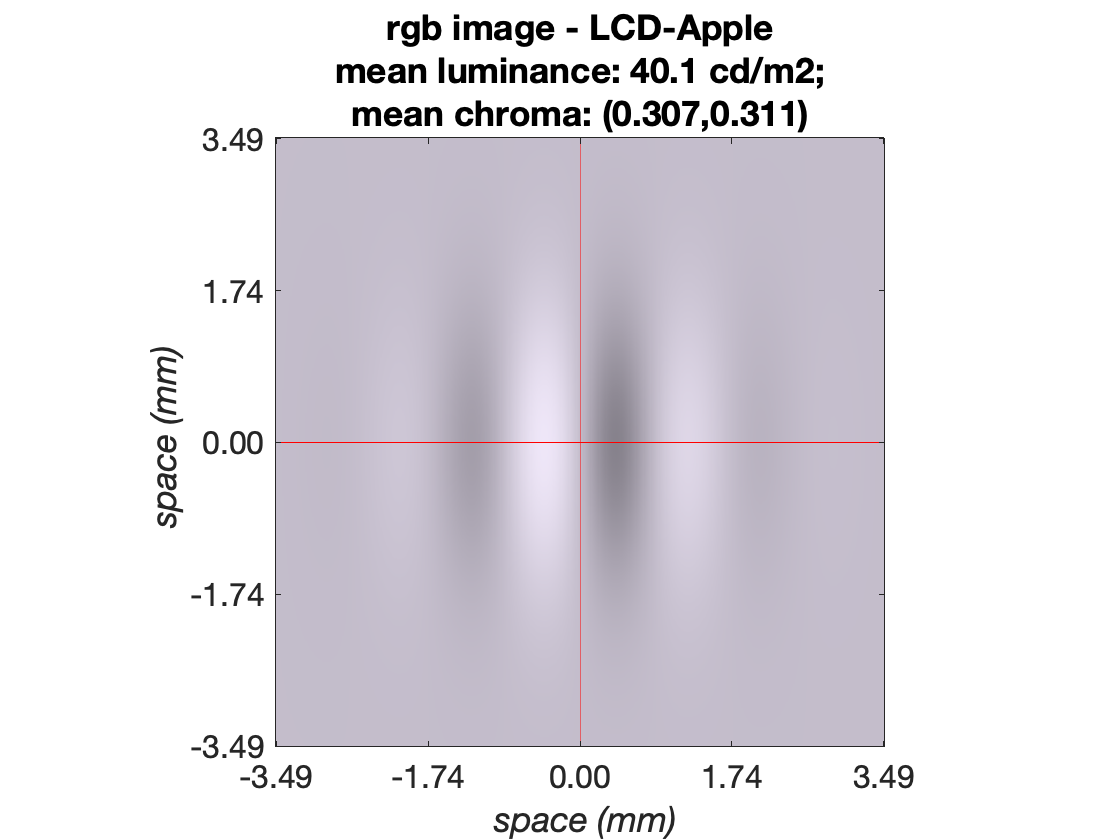

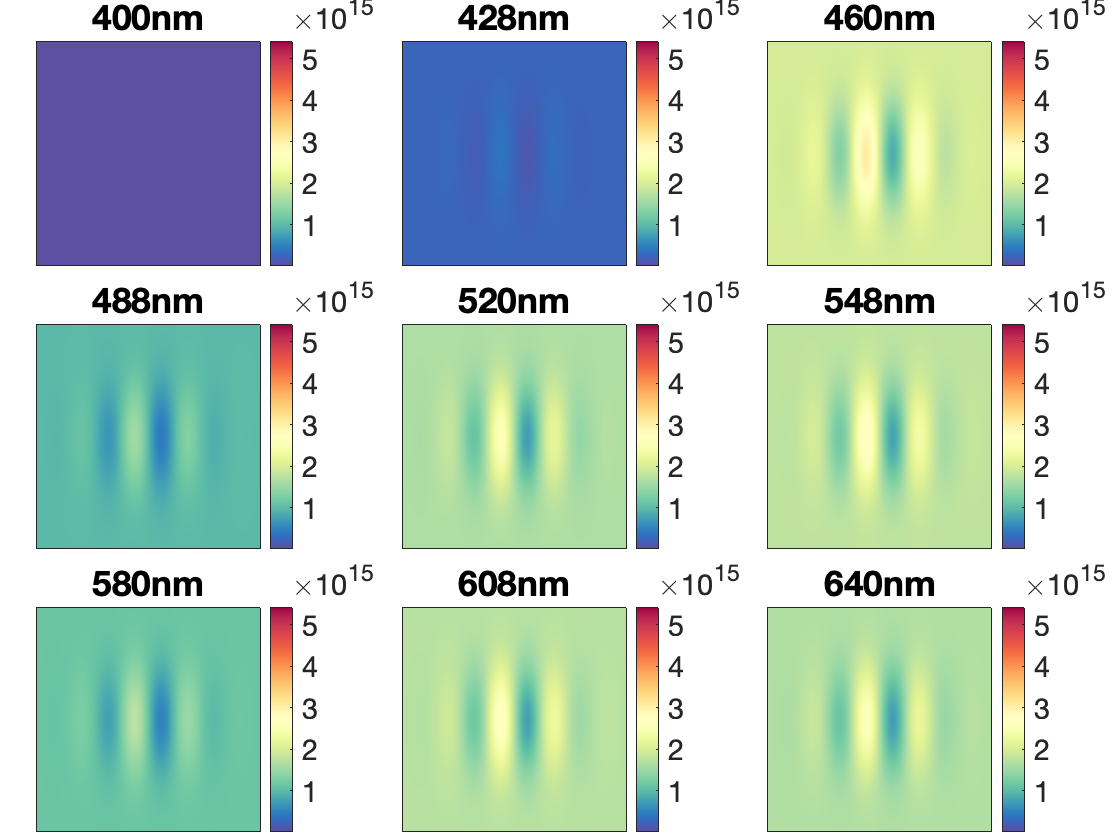

%% Create presentation display and place it 10 cm in front of the eye
presentationDisplay = displayCreate('LCD-Apple', 'viewing distance', 0.10);

%% parameter struct for a low spatial frequency Gabor stimulus 
stimParams = struct(...
    'spatialFrequencyCyclesPerDeg', 1.0, ... % 1.0 cycles/deg
    'orientationDegs', 0, ...               % 0 degrees
    'phaseDegs', 90, ...                    % spatial phase degrees
    'sizeDegs', 4.0, ...                    % 2 x 2 size
    'sigmaDegs', 2/3, ...                   % sigma of Gaussian envelope
    'contrast', 0.6,...                     % 0.6 Michelson contrast
    'meanLuminanceCdPerM2', 40, ...         % 40 cd/m2 mean luminance
    'pixelsAlongWidthDim', [], ...          % pixels- width dimension
    'pixelsAlongHeightDim', [] ...          % pixel- height dimension
    );


% Generate a scene representing the Gabor stimulus with the above params as
% realized on the presentationDisplay
realizedStimulusScene = generateGaborScene(...
    'stimParams', stimParams,...
    'presentationDisplay', presentationDisplay);

% Visualize different aspects of the generated scene
visualizeScene(realizedStimulusScene);

# **Step 2.** Compute the optical image using the default TreeShrew optics

We employ the default treeshrew optics which are based on a Gaussian PSF. The scene is passed through the optics model to compute the retinal image.

### Step 2.1 Generate the default treeshrew optics model

Also visualize the PSF and OTF. 

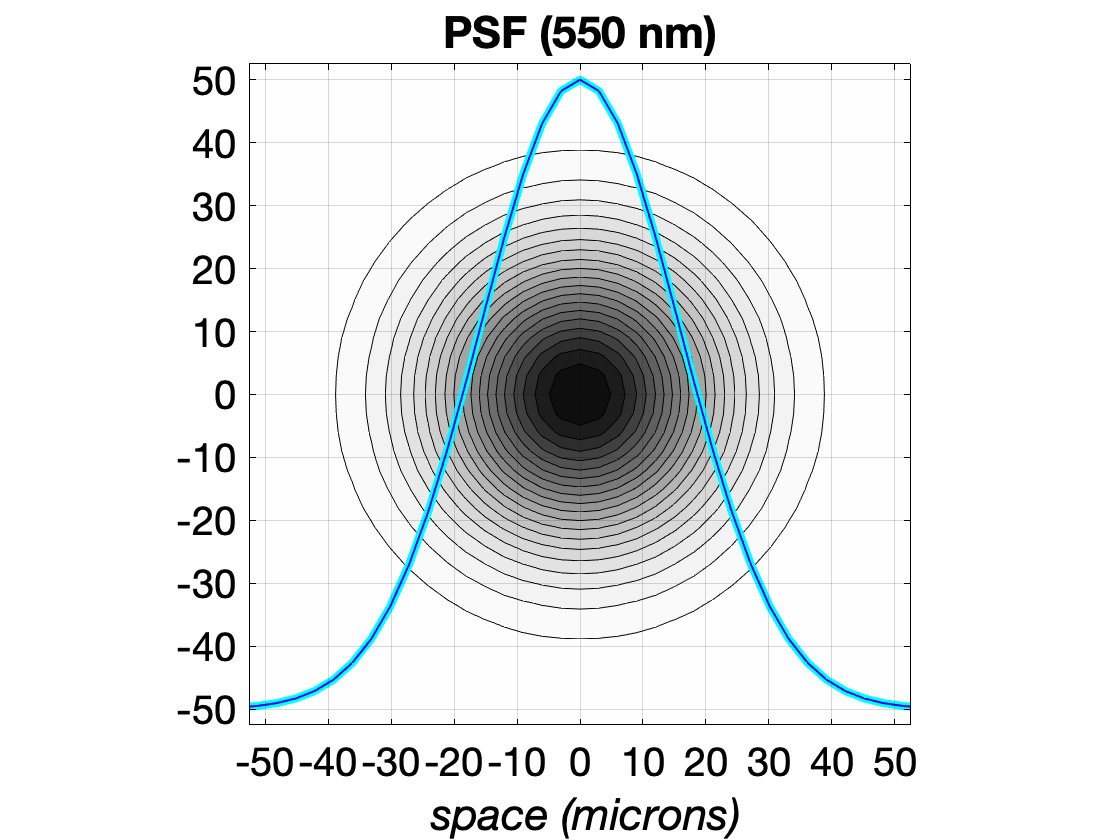

%% Generate wavefront-aberration derived human optics
theOI = oiTreeShrewCreate('inFocusPSFsigmaMicrons', 20);

% Visualize the PSFs and OTFs
visualizedSpatialSupportArcMin = 100;
visualizedSpatialSfrequencyCPD = 4;

% Visualize the PSF at 550 nm
visualizePSF(theOI, 550, visualizedSpatialSupportArcMin);

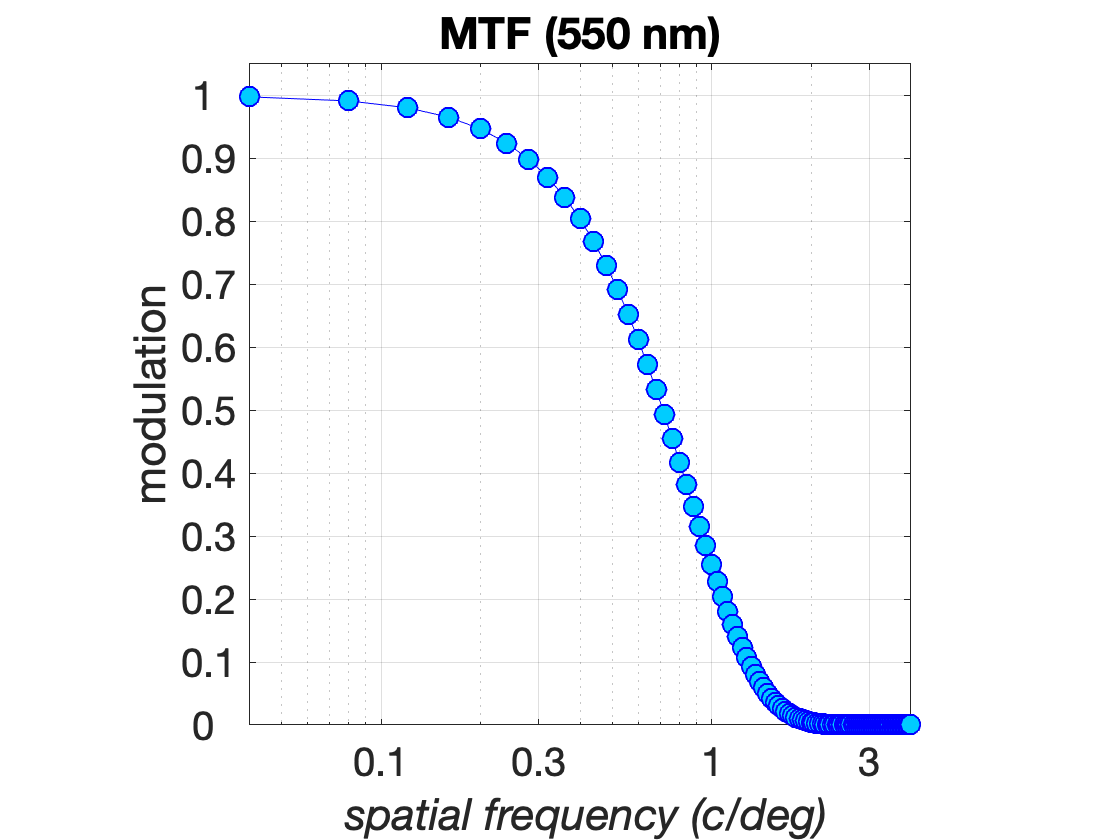

visualizeOTF(theOI, 550, visualizedSpatialSfrequencyCPD);

### Step 2.2 Generate the retinal optical image by passing the scene though the optics

Also visualize the retinal image.

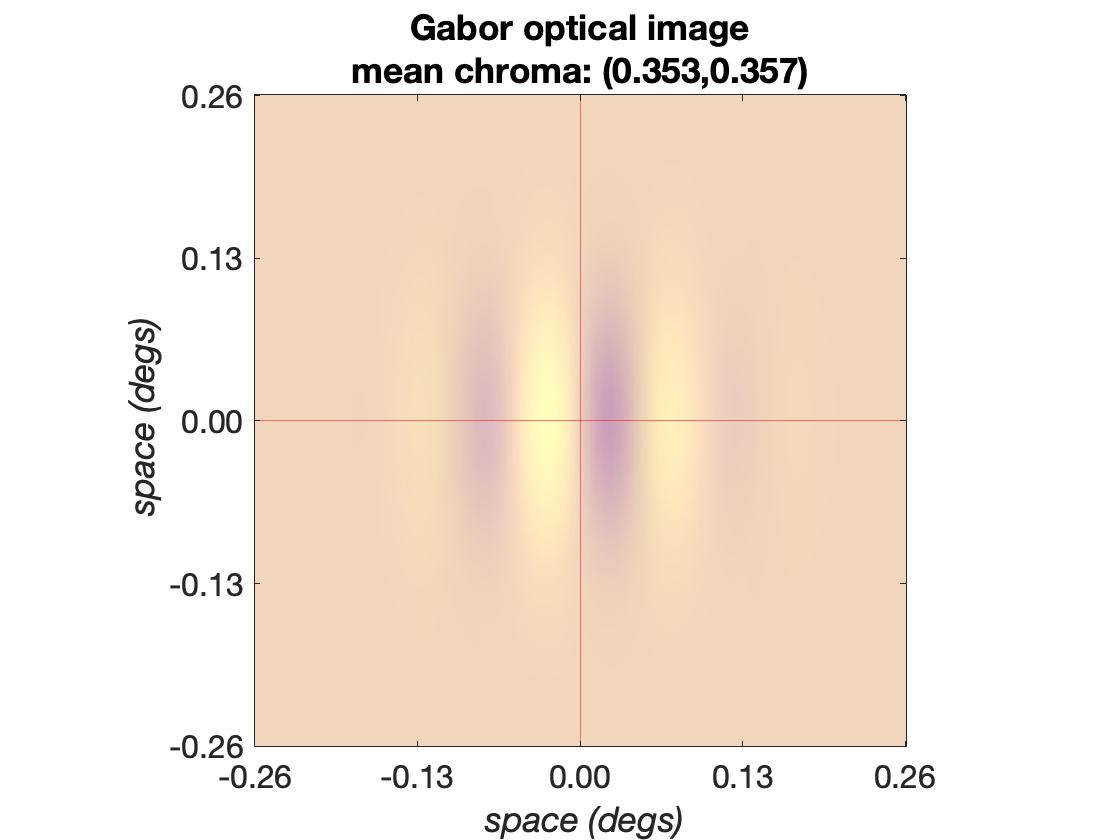

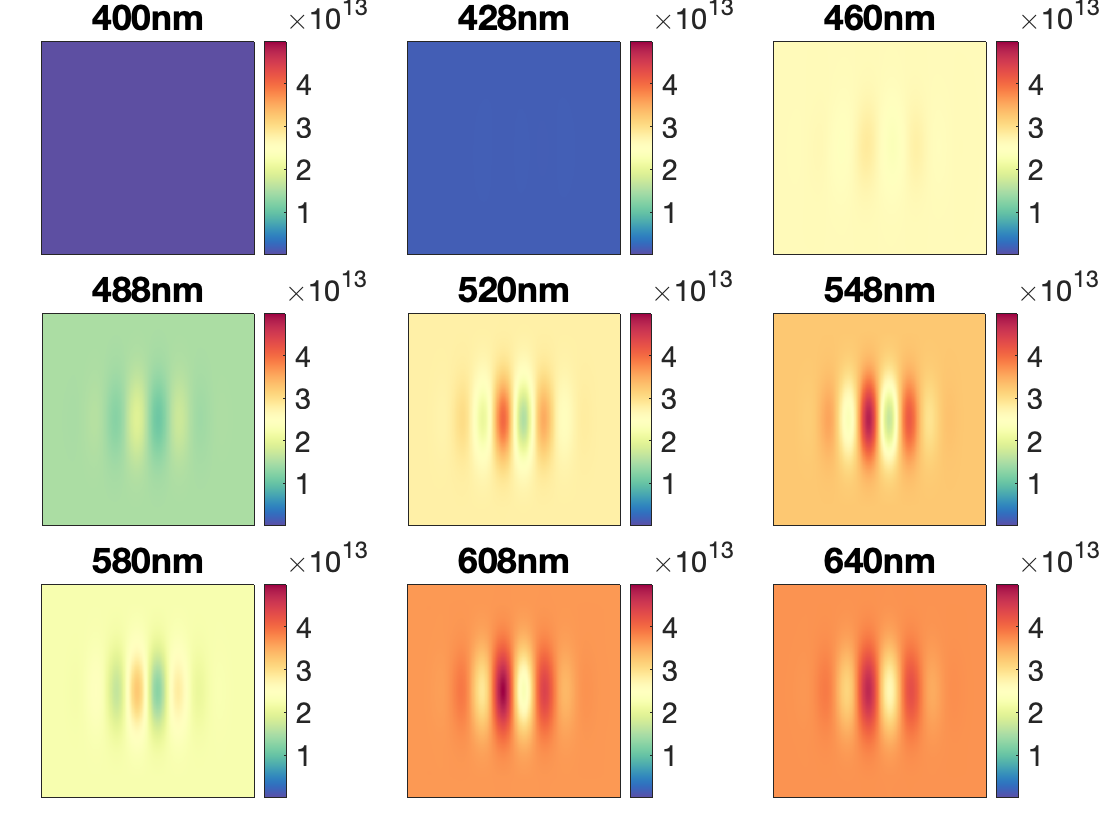

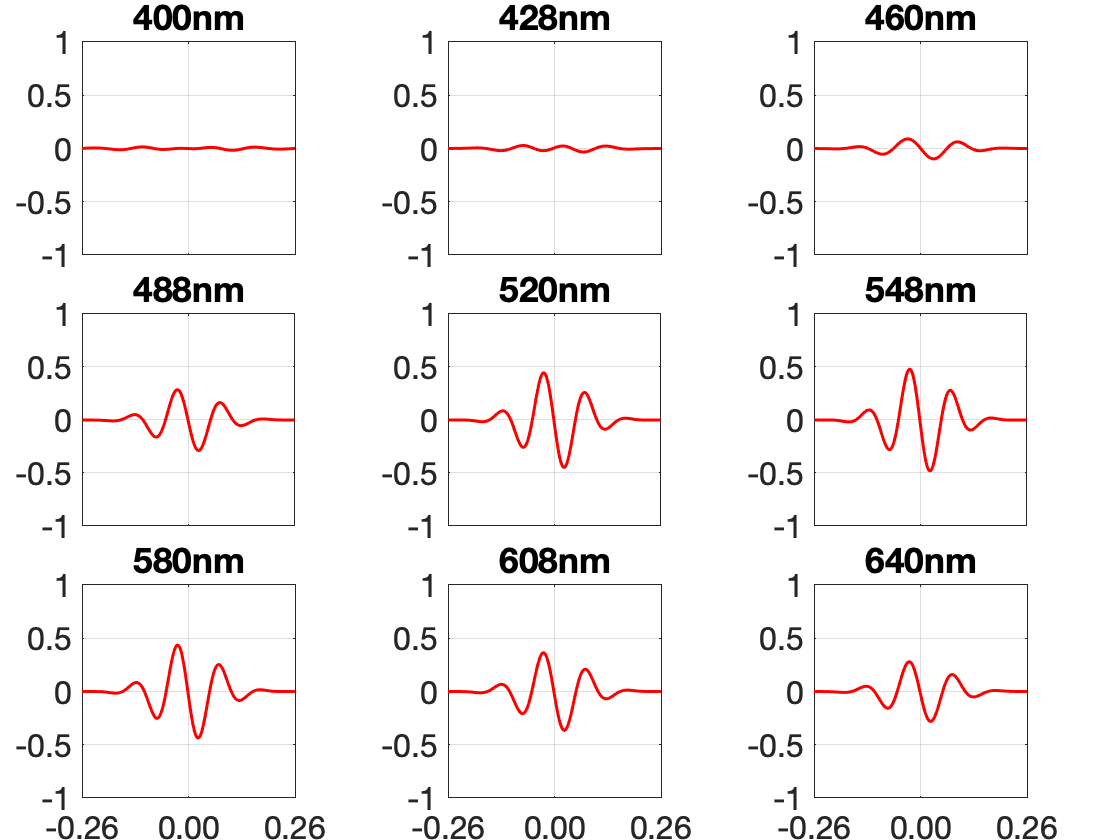

%% Compute the retinal image
theOI = oiCompute(theOI, realizedStimulusScene);

%% Visualize different aspects of the computed optical image
visualizeOpticalImage(theOI, 'displayRetinalContrastProfiles', true);